A certain molecule  **A** is converted to  **B** at a rate of  **k1** =0.5 min-1 in a cell. The reverse reaction occurs at a rate of  **k2** =0.3 min ^-1 . Initially, the concentrations of  **A** and  **B** are 700 and 500 nM, respectively.

A. Solve the system of ODEs for the concentrations of A and B over time. Plot concentrations of A and B over time.

clear all;
syms k1 k2
syms b(t) a(t)
aux1 = unique([diff(a(t), t) == -(k1 * a(t)) + k2 * b(t), diff(b(t), t) == k1 * a(t) - k2 * b(t), a(sym(0)) == sym(700), b(sym(0)) == sym(500)])

$$aux1 = \left(\begin{array}{cccc} \frac{\partial }{\partial t}a\left(t\right)=k_{2}\,b\left(t\right)-k_{1}\,a\left(t\right) & \frac{\partial }{\partial t}b\left(t\right)=k_{1}\,a\left(t\right)-k_{2}\,b\left(t\right) & a\left(0\right)=700 & b\left(0\right)=500 \end{array}\right)$$

odeqn = subs(symfun(aux1, symvar(unique([a(t), b(t)]))), {k1, k2}, {vpa('0.5'), vpa('0.3')})

$$odeqn(t) = \left(\begin{array}{cccc} \frac{\partial }{\partial t}a\left(t\right)=0.3\,b\left(t\right)-0.5\,a\left(t\right) & \frac{\partial }{\partial t}b\left(t\right)=0.5\,a\left(t\right)-0.3\,b\left(t\right) & a\left(0\right)=700 & b\left(0\right)=500 \end{array}\right)$$

aux2 = dsolve(odeqn) % return [y1 ...yn]

aux2 = struct with fields:
    b: [1×1 sym]
    a: [1×1 sym]

sol = aux2(1)

sol = struct with fields:
    b: [1×1 sym]
    a: [1×1 sym]

at = simplify(sol.a)

$$at = 250.0\,{\mathrm{e}}^{-0.8\,t}+450.0$$

bt = simplify(sol.b)

$$bt = 750.0-250.0\,{\mathrm{e}}^{-0.8\,t}$$

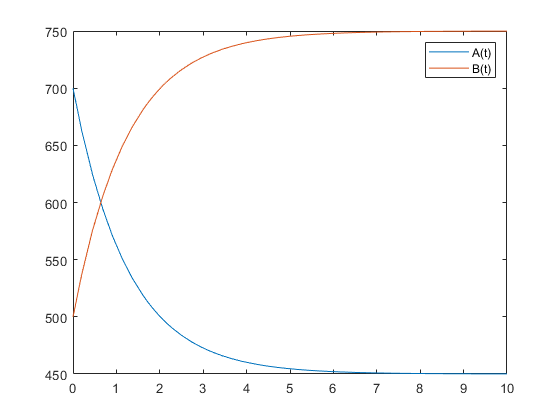


figure
fplot (at, [0, 10])
hold on
fplot(bt, [0 10])
hold off
legend('A(t)', 'B(t)')

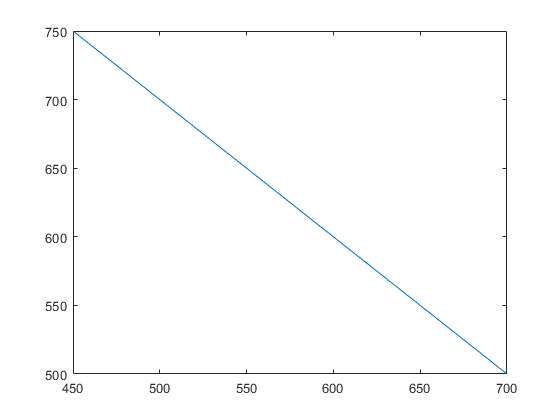

fplot (at, bt, [0 10])

B. Now let's solve the same problem using matrix notation. (not required)

F = @aux7 %create handles to anonymous functions

F = function_handle with value:
    @aux7


K = reshape([-k1, k2; k1, -k2], 2, 2)

$$K = \left(\begin{array}{cc} -k_{1} & k_{2}\\ k_{1} & -k_{2} \end{array}\right)$$


K = subs(K, {k1, k2}, {vpa('0.5'), vpa('0.3')})

$$K = \left(\begin{array}{cc} -0.5 & 0.3\\ 0.5 & -0.3 \end{array}\right)$$

F(t)

$$ans = \left(\begin{array}{c} a\left(t\right)\\ b\left(t\right) \end{array}\right)$$

K*F(t)

$$ans = \left(\begin{array}{c} 0.3\,b\left(t\right)-0.5\,a\left(t\right)\\ 0.5\,a\left(t\right)-0.3\,b\left(t\right) \end{array}\right)$$

syms aux8
subs(diff(F(aux8), aux8), aux8, t) 

$$ans = \left(\begin{array}{c} \frac{\partial }{\partial t}a\left(t\right)\\ \frac{\partial }{\partial t}b\left(t\right) \end{array}\right)$$

syms aux8
aux9 = subs(diff(F(aux8), aux8), aux8, t) - K * F(t)

$$aux9 = \left(\begin{array}{c} \frac{\partial }{\partial t}a\left(t\right)+0.5\,a\left(t\right)-0.3\,b\left(t\right)\\ \frac{\partial }{\partial t}b\left(t\right)-0.5\,a\left(t\right)+0.3\,b\left(t\right) \end{array}\right)$$

transpose(aux9(:))

$$ans = \left(\begin{array}{cc} \frac{\partial }{\partial t}a\left(t\right)+0.5\,a\left(t\right)-0.3\,b\left(t\right) & \frac{\partial }{\partial t}b\left(t\right)-0.5\,a\left(t\right)+0.3\,b\left(t\right) \end{array}\right)$$

aux10 = num2cell(transpose(aux9(:)))

aux10 = 1×2 cell array
    {1×1 sym}    {1×1 sym}


aux11 = unique([aux10{:}, a(sym(0)) == sym(700), b(sym(0)) == sym(500)])

$$aux11 = \left(\begin{array}{cccc} a\left(0\right)=700 & b\left(0\right)=500 & \frac{\partial }{\partial t}a\left(t\right)+0.5\,a\left(t\right)-0.3\,b\left(t\right) & \frac{\partial }{\partial t}b\left(t\right)-0.5\,a\left(t\right)+0.3\,b\left(t\right) \end{array}\right)$$

aux12 = dsolve(aux11)

aux12 = struct with fields:
    b: [1×1 sym]
    a: [1×1 sym]


sol = aux12(1)

sol = struct with fields:
    b: [1×1 sym]
    a: [1×1 sym]


at = simplify(sol.a)

$$at = 250.0\,{\mathrm{e}}^{-0.8\,t}+450.0$$

aux12 = dsolve(symfun(aux11, symvar(unique([a(t), b(t)])))); %Solve system of differential equations
sol = aux12(1)

sol = struct with fields:
    b: [1×1 sym]
    a: [1×1 sym]


at = simplify(sol.a)

$$at = 250.0\,{\mathrm{e}}^{-0.8\,t}+450.0$$

bt = simplify(sol.b)

$$bt = 750.0-250.0\,{\mathrm{e}}^{-0.8\,t}$$

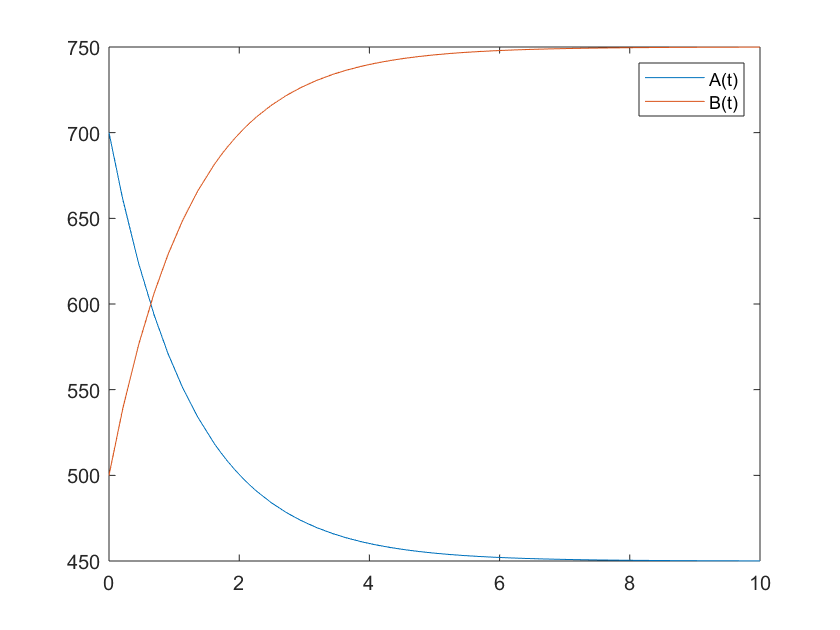

figure
fplot (at, [0, 10])
hold on
fplot(bt, [0 10])
hold off
legend('A(t)', 'B(t)')

C. At what time are the concentrations of the 2 metabolites equal?

tequal = simplify(solve(at == bt, t, 'Real', true))

$$tequal = 0.63853202970748835400689262037958$$

D. What are the steady-state concentrations of A and B?

Easy to see exp(-.8*t) will go to zero, but let's have Matlab figure it out for us:

limit(at, t, sym(inf))

$$ans = 450.0$$


limit(bt, t, sym(inf))

$$ans = 750.0$$

## Local Functions

function returnValue = aux7(t)
a = evalin('base', 'a');
b = evalin('base', 'b');

returnValue = [a(t); b(t)];
end